# Credit Scorecard Development - v1.2

## Scope

ModelName = 'Refaat 2011 Credit Card Model';
ModelVersion = '1.2';
ModelStatus = 'Draft';
Title = 'Refaat 2011 Credit Card Model';
Subject = 'Model Development Documentation';

## Initialize Data

Load dataset from Refaat 2011

whos -file CreditCardData

  Name             Size            Bytes  Class    Attributes

  data              -              84876  table              
  dataMissing       -              84876  table              
  dataWeights       -              94720  table              



load CreditCardData.mat

Standardize variable names

data.Properties.VariableNames{'CustID'} = 'IDVar';
data.Properties.VariableNames{'status'} = 'ResponseVar';
dataMissing.Properties.VariableNames{'CustID'} = 'IDVar';
dataMissing.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'CustID'} = 'IDVar';
dataWeights.Properties.VariableNames{'status'} = 'ResponseVar';
dataWeights.Properties.VariableNames{'RowWeights'} = 'WeightsVar';

filteredData = dataMissing;

summary(dataMissing(:,'CustAge'))


Description:  Credit card dataset, from: M. Refaat, Credit Risk Scorecards, lulu.com, 2011.

Variables:

    CustAge: 1200×1 double

        Values:

            Min              21    
            Median           45    
            Max              74    
            NumMissing       30    



Set the response variable to the status column

responseVar = "ResponseVar";

Remove the ID variable from the list of predictors

idVar = "IDVar";

Create a separate bin for missing data values

binMissingData = true;

Use observation weights if they are present

weightsVar = "WeightsVar";
if ~ismember( weightsVar, dataMissing.Properties.VariableNames )
    weightsVar = '';
end

## Create The Credit Scorecard

sc = creditscorecard(dataMissing,...
    'IDVar',idVar,...
    'ResponseVar',responseVar,...
    'BinMissingData',binMissingData,...
    'WeightsVar',weightsVar);
disp(sc)

  creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'ResponseVar'
               WeightsVar: ''
                 VarNames: {1×11 cell}
        NumericPredictors: {'CustAge'  'TmAtAddress'  'CustIncome'  'TmWBank'  'AMBalance'  'UtilRate'}
    CategoricalPredictors: {'ResStatus'  'EmpStatus'  'OtherCC'}
           BinMissingData: 1
                    IDVar: 'IDVar'
            PredictorVars: {1×9 cell}
                     Data: [1200×11 table]



Launch the Binning Explorer

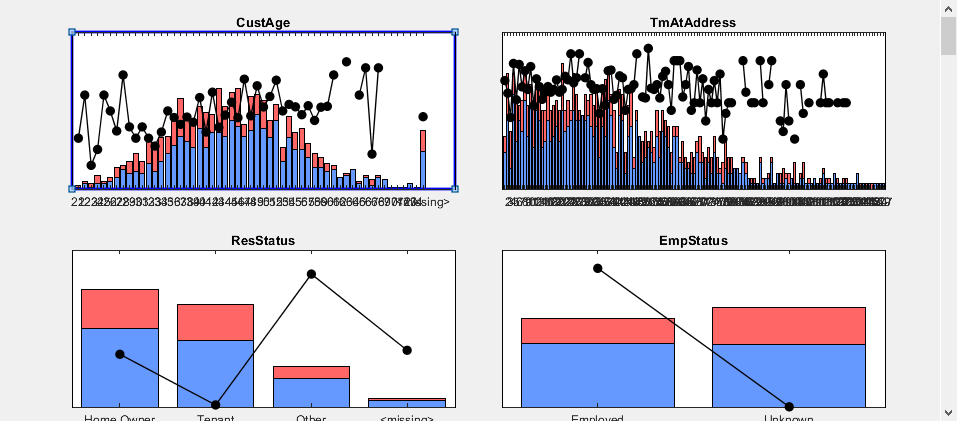

UI figure cannot be added to "ToolGroup".  Use regular figure instead.


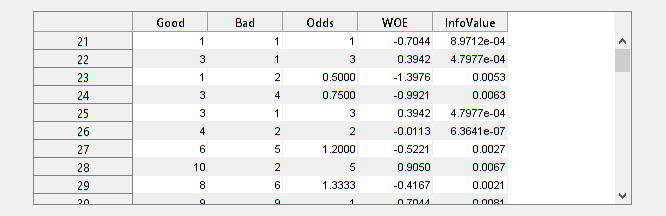

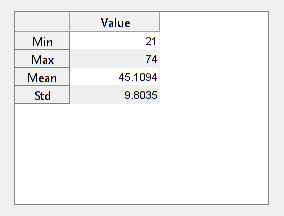

binningExplorer( sc )

## Feature Engineering

Automatically bin the scorecard data

sc_binned = autobinning( sc );

## Model Fitting

Fit a logistic regression model to the WOE data. `fitmodel` internally bins the training data, transforms it into WOE values, maps the response variable so that `'Good'` is `1`, and fits a linear logistic regression model. By default, `fitmodel` uses a stepwise procedure to determine which predictors should be in the model.

[sc_binned,mdl] = fitmodel(sc_binned);

1. Adding CustIncome, Deviance = 1490.8527, Chi2Stat = 32.588614, PValue = 1.1387992e-08
2. Adding TmWBank, Deviance = 1467.1415, Chi2Stat = 23.711203, PValue = 1.1192909e-06
3. Adding AMBalance, Deviance = 1455.5715, Chi2Stat = 11.569967, PValue = 0.00067025601
4. Adding EmpStatus, Deviance = 1447.3451, Chi2Stat = 8.2264038, PValue = 0.0041285257
5. Adding CustAge, Deviance = 1442.8477, Chi2Stat = 4.4974731, PValue = 0.033944979
6. Adding ResStatus, Deviance = 1438.9783, Chi2Stat = 3.86941, PValue = 0.049173805
7. Adding OtherCC, Deviance = 1434.9751, Chi2Stat = 4.0031966, PValue = 0.045414057

Generalized linear regression model:
    logit(ResponseVar) ~ 1 + CustAge + ResStatus + EmpStatus + CustIncome + TmWBank + OtherCC + AMBalance
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________

scores = probdefault(sc_binned,sc_binned.Data);

Include, or "force," a predictor in the logistic regression model, even though the stepwise method did not include it in the fitted model.

[sc_fitted,mdl2] = fitmodel( sc_binned );

1. Adding CustIncome, Deviance = 1490.8527, Chi2Stat = 32.588614, PValue = 1.1387992e-08
2. Adding TmWBank, Deviance = 1467.1415, Chi2Stat = 23.711203, PValue = 1.1192909e-06
3. Adding AMBalance, Deviance = 1455.5715, Chi2Stat = 11.569967, PValue = 0.00067025601
4. Adding EmpStatus, Deviance = 1447.3451, Chi2Stat = 8.2264038, PValue = 0.0041285257
5. Adding CustAge, Deviance = 1442.8477, Chi2Stat = 4.4974731, PValue = 0.033944979
6. Adding ResStatus, Deviance = 1438.9783, Chi2Stat = 3.86941, PValue = 0.049173805
7. Adding OtherCC, Deviance = 1434.9751, Chi2Stat = 4.0031966, PValue = 0.045414057

Generalized linear regression model:
    logit(ResponseVar) ~ 1 + CustAge + ResStatus + EmpStatus + CustIncome + TmWBank + OtherCC + AMBalance
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________

mdl2 = mdl2.addTerms( 'UtilRate' )

mdl2 = Generalized linear regression model:
    logit(ResponseVar) ~ 1 + CustAge + ResStatus + EmpStatus + CustIncome + TmWBank + OtherCC + AMBalance + UtilRate
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)     0.70229    0.063959       10.98    4.7498e-28
    CustAge         0.57427     0.25711      2.2336       0.02551
    ResStatus        1.3633     0.66983      2.0352       0.04183
    EmpStatus       0.88366     0.29292      3.0167     0.0025557
    CustIncome      0.73522     0.21603      3.4033    0.00066589
    TmWBank          1.1062     0.23304      4.7469    2.0653e-06
    OtherCC

sc_fitted = setmodel(sc_fitted,mdl2.PredictorNames,mdl2.Coefficients.Estimate);

## Model Validation

The `creditscorecard` class supports three validation methods, the Cumulative Accuracy Profile (CAP), the Receiver Operating Characteristic (ROC), and the Kolmogorov-Smirnov (K-S) statistic.

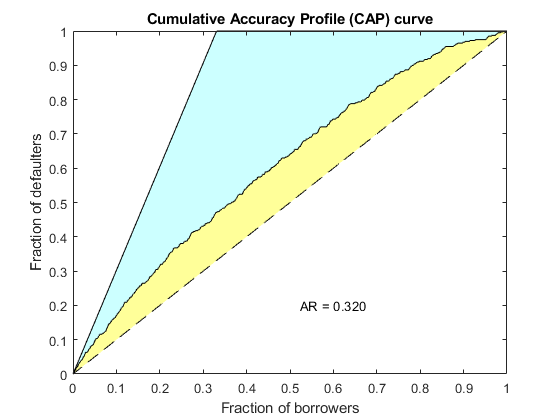

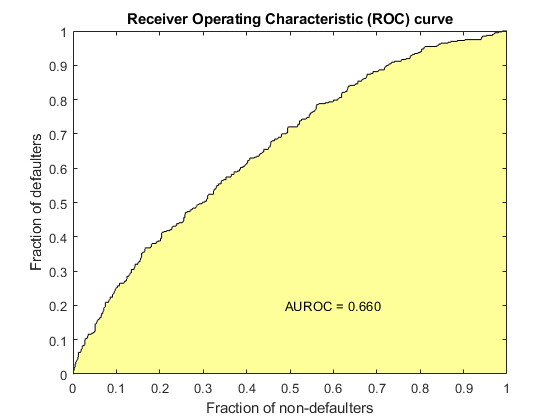

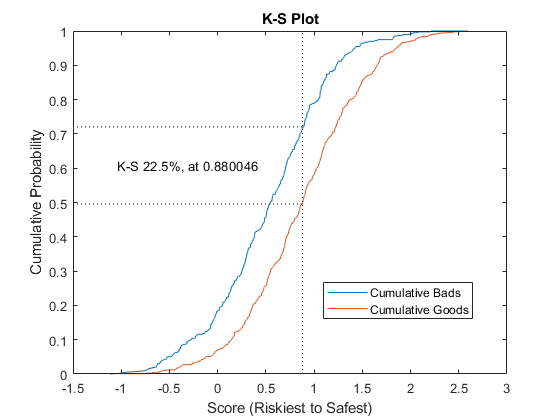

Stats = 4×2 table
            Measure              Value 
    ________________________    _______

    {'Accuracy Ratio'      }    0.32016
    {'Area under ROC curve'}    0.66008
    {'KS statistic'        }    0.22476
    {'KS score'            }    0.88005


T = 1104×9 table
     Scores     ProbDefault    TrueBads    FalseBads    TrueGoods    FalseGoods    Sensitivity    FalseAlarm      PctObs  
    ________    ___________    ________    _________    _________    __________    ___________    __________    __________

     -1.1186      0.75372          0           1           802          397                 0     0.0012453     0.00083333
      -0.987      0.72849          1           1           802          396         0.0025189     0.0012453      0.0016667
    -0.96687      0.72449          2           1           802          395         0.0050378     0.0012453         0.0025
    -0.81833      0.69388          3           1           80

[Stats,T] = validatemodel(sc_fitted,'Plot',{'CAP','ROC','KS'})

## Challenger Model

We compare the performance of the logistic regression fitted with the scorecard data with alternative machine learning methods. 

To do this, we extract the binned WOE values from the scorecard.

binnedFeatures = bindata( sc_fitted );
predictorVars = sc_fitted.PredictorVars;

## **Assessment of Predictive Ability of Credit Rating Models**

**Table of Contents**

Assessment of Predictive Ability of Credit Rating Models

Credit scoring is one of the most widely used credit risk analysis tools to rank borrowers by their credit worthiness. Credit scoring is performed using a credit scorecard. Credit scorecards model different characteristics of a customer (age, residential status, etc.), translate them into points and sum the points to compute the credit score. The credit score summarizes the credit worthiness of customers. High credit scores correspond to low-risk customers, and conversely. 

In order to assess the predictive ability of a credit scorecard there exists several statistical methodologies, which require the following:

- scores associated to each name or observation in the credit scorecard ($scores$)

- probability of default corresponding to each score ($defaultProbs$)

- indicator variable to signal if an observation is a defaulter or otherwise ($defaultIndicators$)

scores = score(sc_binned);
defaultProbs = probdefault(sc_binned);
defaultIndicators = sc_binned.Data.(sc_binned.ResponseVar) ~= sc_binned.GoodLabel;

 The subsequent sections each calculate one model validation metric in a self-contained manner. The results are stored in a collection object:

MH = mrm.data.validation.MetricsHandler;

and summarised at the end of the script.